clear

## EQUATIONS OF MOTION


syms M R L1 L2 Mt1 Mt2 Mt3 mu beta1 beta2
U=-M*mu/R+(mu/(2*R^3))*(Mt1*L1^2+Mt2*L2^2+2*Mt3*L1*L2*cos(beta1-beta2))-(3*mu/(2*R^3))*(Mt1*L1^2*cos(beta1)^2+Mt2*L2^2*cos(beta2)^2+2*Mt3*L1*L2*cos(beta1)*cos(beta2));
syms Rdot thetadot w1(t) w2(t) theta
T=(1/2)*M*(Rdot^2+R^2*thetadot^2)+(1/2)*Mt1*w1^2*L1^2+(1/2)*Mt2*w2^2*L2^2+Mt3*w1*w2*L1*L2*cos(beta1-beta2);
L=T-U;
% R-Equation
DL_Rdot=diff(L,Rdot);
syms Rdott(t) beta1t(t) beta2t(t) Rt(t)
DL_Rdott=subs(DL_Rdot,Rdot,Rdott);
eqmt=diff(DL_Rdott,t)-subs(diff(L,R),{R,beta1,beta2},{Rt,beta1t,beta2t});
syms Rdot(t) beta1(t) beta2(t) 
eqmR=subs(eqmt,{Rdott,Rt,beta1t,beta2t},{Rdot,R,beta1,beta2})

$$eqmR(t) = M\,\frac{\partial }{\partial t}\mathrm{Rdot}\left(t\right)+\frac{9\,\mu \,\left({\mathrm{Mt}}_{1}\,{L_{1}}^{2}\,{\cos\left(\beta_{1}\left(t\right)\right)}^{2}+2\,{\mathrm{Mt}}_{3}\,L_{1}\,L_{2}\,\cos\left(\beta_{1}\left(t\right)\right)\,\cos\left(\beta_{2}\left(t\right)\right)+{\mathrm{Mt}}_{2}\,{L_{2}}^{2}\,{\cos\left(\beta_{2}\left(t\right)\right)}^{2}\right)}{2\,R^{4}}-\frac{3\,\mu \,\left({\mathrm{Mt}}_{1}\,{L_{1}}^{2}+2\,{\mathrm{Mt}}_{3}\,\cos\left(\beta_{1}\left(t\right)-\beta_{2}\left(t\right)\right)\,L_{1}\,L_{2}+{\mathrm{Mt}}_{2}\,{L_{2}}^{2}\right)}{2\,R^{4}}+\frac{M\,\mu }{R^{2}}-M\,R\,{\mathrm{thetadot}}^{2}$$

% Theta-Equation
syms M R L1 L2 Mt1 Mt2 Mt3 mu beta1 beta2
syms Rdot thetadot w1(t) w2(t) theta
syms beta1dot beta2dot 
L_new=subs(L,{w1,w2},{thetadot+beta1dot,thetadot+beta2dot});
DL_thetadot=diff(L_new,thetadot);
syms thetadott(t) Rt(t) beta1t(t) beta2t(t) beta1dott(t) beta2dott(t)
DL_thetadott=subs(DL_thetadot,{thetadot R beta1 beta2 beta1dot beta2dot},...
    {thetadott Rt beta1t beta2t beta1dott beta2dott});
eqmt=diff(DL_thetadott,t)-subs(diff(L_new,theta),{R,beta1,beta2},{Rt,beta1t,beta2t});
syms thetadot(t) R(t) beta1(t) beta2(t) beta1dot(t) beta2dot(t)
eqmtheta_1=subs(eqmt,{thetadott Rt beta1t beta2t beta1dott beta2dott},...
    {thetadot R beta1 beta2 beta1dot beta2dot});
syms w1dot w2dot
eqmtheta=subs(eqmtheta_1,{thetadot+beta1dot,thetadot+beta2dot,diff(thetadot,t)+diff(beta1dot,t)...
    ,diff(thetadot,t)+diff(beta2dot,t)},{w1,w2,w1dot,w2dot})

$$eqmtheta(t) = \begin{array}{l} M\,{R\left(t\right)}^{2}\,\frac{\partial }{\partial t}\mathrm{thetadot}\left(t\right)+{L_{1}}^{2}\,{\mathrm{Mt}}_{1}\,\mathrm{w1dot}+{L_{2}}^{2}\,{\mathrm{Mt}}_{2}\,\mathrm{w2dot}+2\,M\,R\left(t\right)\,\mathrm{thetadot}\left(t\right)\,\frac{\partial }{\partial t}R\left(t\right)+L_{1}\,L_{2}\,{\mathrm{Mt}}_{3}\,\mathrm{w1dot}\,\sigma_{3}+L_{1}\,L_{2}\,{\mathrm{Mt}}_{3}\,\mathrm{w2dot}\,\sigma_{3}-L_{1}\,L_{2}\,{\mathrm{Mt}}_{3}\,\sigma_{2}\,w_{1}\left(t\right)\,\sigma_{1}-L_{1}\,L_{2}\,{\mathrm{Mt}}_{3}\,\sigma_{2}\,w_{2}\left(t\right)\,\sigma_{1}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}\beta_{1}\left(t\right)-\frac{\partial }{\partial t}\beta_{2}\left(t\right)\\ \sigma_{2}=\sin\left(\beta_{1}\left(t\right)-\beta_{2}\left(t\right)\right)\\ \sigma_{3}=\cos\left(\beta_{1}\left(t\right)-\beta_{2}\left(t\right)\right) \end{array}$$

% Beta1-Equation
syms beta1dot beta2dot beta1 beta2 thetadot
DL_beta1dot=diff(L_new,beta1dot);
syms thetadott(t) beta1t(t) beta2t(t) beta1dott(t) beta2dott(t) Rt(t)
DL_beta1dott=subs(DL_beta1dot,{thetadot beta1 beta2 beta1dot beta2dot},{thetadott beta1t beta2t beta1dott beta2dott});
eqmt=diff(DL_beta1dott,t)-subs(diff(L_new,beta1),{R,beta1,beta2},{Rt,beta1t,beta2t});
syms thetadot(t) beta1(t) beta2(t) beta1dot(t) beta2dot(t) R(t)
eqmbeta1_1=subs(eqmt,{thetadott Rt beta1t beta2t beta1dott beta2dott},{thetadot R beta1 beta2 beta1dot beta2dot});
eqmbeta1_2=subs(eqmbeta1_1,{thetadot+beta1dot,thetadot+beta2dot,diff(thetadot,t)+diff(beta1dot,t)...
    ,diff(thetadot,t)+diff(beta2dot,t)},{w1,w2,w1dot,w2dot});
syms thetadot beta1dot beta2dot
eqmbeta1=subs(eqmbeta1_2,{thetadot+beta1dot,thetadot+beta2dot},{w1,w2})

$$eqmbeta1(t) = \begin{array}{l} {L_{1}}^{2}\,{\mathrm{Mt}}_{1}\,\mathrm{w1dot}+\frac{3\,\mu \,\left(2\,{\mathrm{Mt}}_{1}\,\cos\left(\beta_{1}\left(t\right)\right)\,\sin\left(\beta_{1}\left(t\right)\right)\,{L_{1}}^{2}+2\,L_{2}\,{\mathrm{Mt}}_{3}\,\cos\left(\beta_{2}\left(t\right)\right)\,\sin\left(\beta_{1}\left(t\right)\right)\,L_{1}\right)}{2\,{R\left(t\right)}^{3}}+L_{1}\,L_{2}\,{\mathrm{Mt}}_{3}\,\mathrm{w2dot}\,\cos\left(\sigma_{1}\right)-L_{1}\,L_{2}\,{\mathrm{Mt}}_{3}\,\sin\left(\sigma_{1}\right)\,w_{2}\left(t\right)\,\left(\frac{\partial }{\partial t}\beta_{1}\left(t\right)-\frac{\partial }{\partial t}\beta_{2}\left(t\right)\right)-\frac{L_{1}\,L_{2}\,{\mathrm{Mt}}_{3}\,\mu \,\sin\left(\sigma_{1}\right)}{{R\left(t\right)}^{3}}+L_{1}\,L_{2}\,{\mathrm{Mt}}_{3}\,\sin\left(\sigma_{1}\right)\,w_{1}\left(t\right)\,w_{2}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\beta_{1}\left(t\right)-\beta_{2}\left(t\right) \end{array}$$

% Beta2-Equation
syms beta1dot beta2dot beta1 beta2 thetadot
DL_beta2dot=diff(L_new,beta2dot);
syms thetadott(t) beta1t(t) beta2t(t) beta1dott(t) beta2dott(t) Rt(t)
DL_beta2dott=subs(DL_beta2dot,{thetadot beta1 beta2 beta1dot beta2dot},{thetadott beta1t beta2t beta1dott beta2dott});
eqmt=diff(DL_beta2dott,t)-subs(diff(L_new,beta2),{R,beta1,beta2},{Rt,beta1t,beta2t});
syms thetadot(t) beta1(t) beta2(t) beta1dot(t) beta2dot(t) R(t)
eqmbeta2_1=subs(eqmt,{thetadott Rt beta1t beta2t beta1dott beta2dott},{thetadot R beta1 beta2 beta1dot beta2dot});
eqmbeta2_2=subs(eqmbeta2_1,{thetadot+beta1dot,thetadot+beta2dot,diff(thetadot,t)+diff(beta1dot,t)...
    ,diff(thetadot,t)+diff(beta2dot,t)},{w1,w2,w1dot,w2dot});
syms thetadot beta1dot beta2dot
eqmbeta2=subs(eqmbeta2_2,{thetadot+beta1dot,thetadot+beta2dot},{w1,w2})

$$eqmbeta2(t) = \begin{array}{l} {L_{2}}^{2}\,{\mathrm{Mt}}_{2}\,\mathrm{w2dot}+\frac{3\,\mu \,\left(2\,{\mathrm{Mt}}_{2}\,\cos\left(\beta_{2}\left(t\right)\right)\,\sin\left(\beta_{2}\left(t\right)\right)\,{L_{2}}^{2}+2\,L_{1}\,{\mathrm{Mt}}_{3}\,\cos\left(\beta_{1}\left(t\right)\right)\,\sin\left(\beta_{2}\left(t\right)\right)\,L_{2}\right)}{2\,{R\left(t\right)}^{3}}+L_{1}\,L_{2}\,{\mathrm{Mt}}_{3}\,\mathrm{w1dot}\,\cos\left(\sigma_{1}\right)-L_{1}\,L_{2}\,{\mathrm{Mt}}_{3}\,\sin\left(\sigma_{1}\right)\,w_{1}\left(t\right)\,\left(\frac{\partial }{\partial t}\beta_{1}\left(t\right)-\frac{\partial }{\partial t}\beta_{2}\left(t\right)\right)+\frac{L_{1}\,L_{2}\,{\mathrm{Mt}}_{3}\,\mu \,\sin\left(\sigma_{1}\right)}{{R\left(t\right)}^{3}}-L_{1}\,L_{2}\,{\mathrm{Mt}}_{3}\,\sin\left(\sigma_{1}\right)\,w_{1}\left(t\right)\,w_{2}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}=\beta_{1}\left(t\right)-\beta_{2}\left(t\right) \end{array}$$

## NUMERIC INTEGRATION

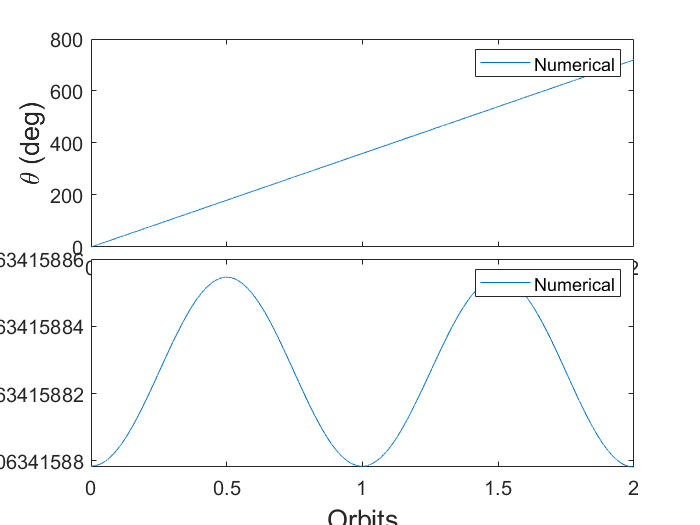


syms M R L1 L2 Mt1 Mt2 Mt3 mu beta1 beta2
m1=10; m2=1; m3=1; L1=1; L2=1 ;
M=m1+m2+m3;
gamma1=(m2+m3)/M; gamma2=m3/M ;
Mt1=m1*gamma1^2+m2*(1-gamma1)^2+m3*(1-gamma1)^2;
Mt2=m1*gamma2^2+m2*gamma2^2+m3*(1-gamma2)^2;
Mt3=m1*gamma1*gamma2-m2*(1-gamma1)*gamma2+m3*(1-gamma1)*(1-gamma2);
mu=3.986*10^5;

% Converting Equation of Motion into first order form
syms Rdot(t) thetadot(t) beta1dot(t) beta2dot(t) beta1 beta2
eqmR=subs(eqmR)==0;
eqmtheta=subs(eqmtheta_1)==0;
eqmbeta1=subs(eqmbeta1_1)==0;
eqmbeta2=subs(eqmbeta2_1)==0;
syms Rddot thetaddot beta1ddot beta2ddot
eqmR=subs(eqmR,diff(Rdot,t),Rddot);
eqmtheta=subs(eqmtheta,diff(thetadot,t),thetaddot);
eqmbeta1=subs(eqmbeta1,diff(beta1dot,t),beta1ddot);
eqmbeta2=subs(eqmbeta2,diff(beta2dot,t),beta2ddot);
syms beta1(t) beta2(t) R(t) theta(t)
eqmR=subs(eqmR,{Rdot,thetadot,beta1dot,beta2dot},...
    {diff(R),diff(theta),diff(beta1),diff(beta2)});
eqmtheta=subs(eqmtheta,{Rdot,thetadot,beta1dot,beta2dot},...
    {diff(R),diff(theta),diff(beta1),diff(beta2)});
eqmbeta1=subs(eqmbeta1,{Rdot,thetadot,beta1dot,beta2dot},...
    {diff(R),diff(theta),diff(beta1),diff(beta2)});
eqmbeta2=subs(eqmbeta2,{Rdot,thetadot,beta1dot,beta2dot},...
    {diff(R),diff(theta),diff(beta1),diff(beta2)});

EqR=diff(R,t,t)==solve(eqmR,Rddot);
Eqtheta=diff(theta,t,t)==solve(eqmtheta,thetaddot);
Eqbeta1=diff(beta1,t,t)==solve(eqmbeta1,beta1ddot);
Eqbeta2=diff(beta2,t,t)==solve(eqmbeta2,beta2ddot);
Eqs=[EqR;Eqtheta;Eqbeta1;Eqbeta2];
[V,Y]=odeToVectorField(Eqs);
F=matlabFunction(V,'vars',{'t','Y'});
% Initial Conditions
R_0=6878; Rdot_0=0;
theta_0=0; thetadot_0=sqrt(mu/R_0^3); % Orbital Angular Velocity (rad/s)
beta1_0=deg2rad(10); beta1dot_0=0.01*thetadot_0; %(rad/s)
beta2_0=deg2rad(-15); beta2dot_0=0.01*thetadot_0; %(rad/s)
% Simulation time
tstart=0;               % Simulation start time (in seconds)  
nor=2;                  % Simulation end time (in orbits)
tperiod=2*pi/thetadot_0;  % Orbital time period (sec)
tend=tperiod*nor; % Simulation end time (in seconds)
tstep=0.5;                % Time step (in seconds) 
t=tstart:tstep:tend;    % Simulation time
init_con=[theta_0;thetadot_0;R_0;Rdot_0;beta1_0;beta1dot_0;beta2_0;beta2dot_0];
options=odeset('abstol',1e-9,'reltol',1e-9);
[t,x]=ode45(F,t,init_con);

theta=thetadot_0*t;
deg2rad=pi/180;
%Plotting
figure(1)
zoom on
subplot(10,1,1:5),plot(theta/(2*pi),x(:,1)/deg2rad);
set(findobj(gca,'Type','line','Color',[0 0 1]),'LineWidth',1)
set(findobj(gca,'Type','axes'),'Fontsize',12)
xlabel('Orbits',"FontSize",16);
ylabel('\theta (deg)',"FontSize",16);
legend('Numerical');
subplot(10,1,6:10),plot(theta/(2*pi),x(:,2)/deg2rad);
set(findobj(gca,'Type','line','Color',[0 0 1]),'LineWidth',1)
set(findobj(gca,'Type','axes'),'Fontsize',12)
xlabel('Orbits',"FontSize",16);
ylabel('\thetadot (deg/sec)',"FontSize",16);
legend('Numerical');

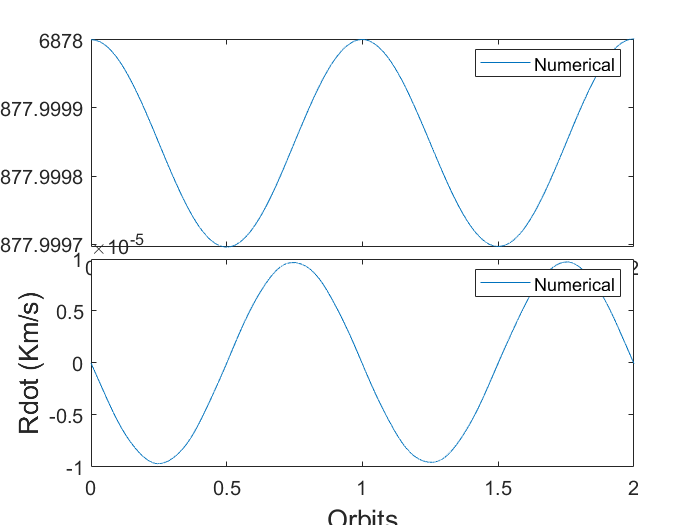


figure(2)
zoom on
subplot(10,1,1:5),plot(theta/(2*pi),x(:,3));
set(findobj(gca,'Type','line','Color',[0 0 1]),'LineWidth',1)
set(findobj(gca,'Type','axes'),'Fontsize',12)
xlabel('Orbits',"FontSize",16);
ylabel('R (Km)',"FontSize",16);
legend('Numerical');
subplot(10,1,6:10),plot(theta/(2*pi),x(:,4)/deg2rad);
set(findobj(gca,'Type','line','Color',[0 0 1]),'LineWidth',1)
set(findobj(gca,'Type','axes'),'Fontsize',12)
xlabel('Orbits',"FontSize",16);
ylabel('Rdot (Km/s)',"FontSize",16);
legend('Numerical');

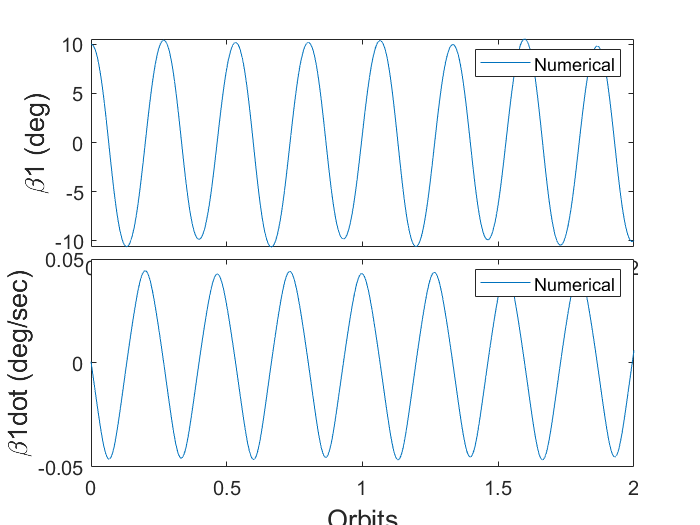


figure(3)
zoom on
subplot(10,1,1:5),plot(theta/(2*pi),x(:,5)/deg2rad);
set(findobj(gca,'Type','line','Color',[0 0 1]),'LineWidth',1)
set(findobj(gca,'Type','axes'),'Fontsize',12)
xlabel('Orbits',"FontSize",16);
ylabel('\beta1 (deg)',"FontSize",16);
legend('Numerical');
subplot(10,1,6:10),plot(theta/(2*pi),x(:,6)/deg2rad);
set(findobj(gca,'Type','line','Color',[0 0 1]),'LineWidth',1)
set(findobj(gca,'Type','axes'),'Fontsize',12)
xlabel('Orbits',"FontSize",16);
ylabel('\beta1dot (deg/sec)',"FontSize",16);
legend('Numerical');

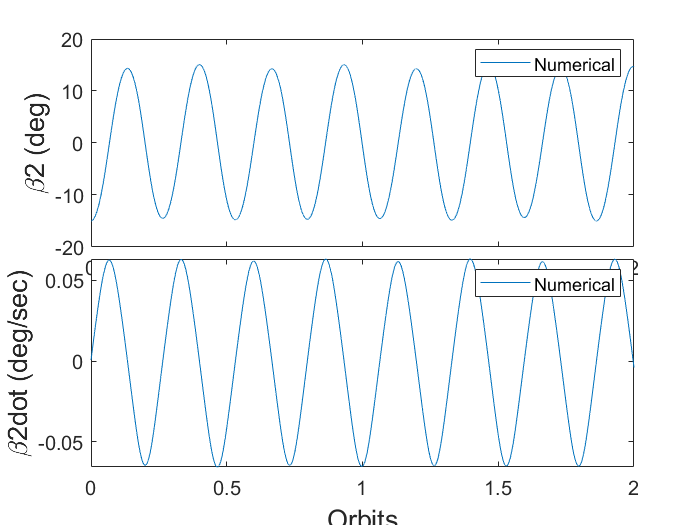


figure(4)
zoom on
subplot(10,1,1:5),plot(theta/(2*pi),x(:,7)/deg2rad);
set(findobj(gca,'Type','line','Color',[0 0 1]),'LineWidth',1)
set(findobj(gca,'Type','axes'),'Fontsize',12)
xlabel('Orbits',"FontSize",16);
ylabel('\beta2 (deg)',"FontSize",16);
legend('Numerical');
subplot(10,1,6:10),plot(theta/(2*pi),x(:,8)/deg2rad);
set(findobj(gca,'Type','line','Color',[0 0 1]),'LineWidth',1)
set(findobj(gca,'Type','axes'),'Fontsize',12)
xlabel('Orbits',"FontSize",16);
ylabel('\beta2dot (deg/sec)',"FontSize",16);
legend('Numerical');